fun = @(x) cos(x(1)) * cos(x(2)) * exp(-(x(1) - pi)^2 - (x(2) - pi)^2);

% number of variables
nvars = 2;

% Lower and upper bounds
lb = [-5, -5];  % lower bounds for [x, y]
ub = [5, 5];    % upper bounds for [x, y]


[x, fval, exitflag, output] = particleswarm(fun, nvars, lb, ub);

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


    

fprintf('Optimal solution: x1 = %f, x2 = %f\n', x(1), x(2));

Optimal solution: x1 = 5.000000, x2 = 3.141593


fprintf('Function value at optimum: %f\n', fval);

Function value at optimum: -0.008972


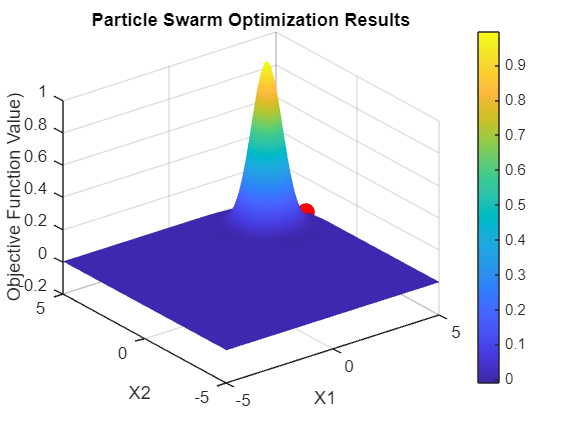



[X1, X2] = meshgrid(linspace(-5, 5, 100), linspace(-5, 5, 100));
Z = cos(X1) .* cos(X2) .* exp(-(X1 - pi).^2 - (X2 - pi).^2);


figure;
surf(X1, X2, Z);
hold on;
plot3(x(1), x(2), fval, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
title('Particle Swarm Optimization Results')
xlabel('X1');
ylabel('X2');
zlabel('Objective Function Value)');

hold off;

shading interp;
colorbar

grid on;